clc; close all; clear;

syms x1 x2 u
Rf=10;
Lf=1;
Cf=0.1;
f1 = -Rf/Lf *x1 + 1/Lf*x2;
f2 = -1/Cf *x1 -1/Cf*(u-x2)*(u-x2-1)*(u-x2-2);
x1eq=0;
x2eq=0;
ueq=1;
%%
Jx = jacobian([f1; f2], [x1; x2])

$$Jx = \left(\begin{array}{cc} -10 & 1\\ -10 & 10\,\left(x_{2}-u+1\right)\,\left(x_{2}-u+2\right)-\left(10\,u-10\,x_{2}\right)\,\left(x_{2}-u+2\right)-\left(10\,u-10\,x_{2}\right)\,\left(x_{2}-u+1\right) \end{array}\right)$$

Ju = jacobian([f1; f2], [u])

$$Ju = \left(\begin{array}{c} 0\\ \left(10\,u-10\,x_{2}\right)\,\left(x_{2}-u+1\right)+\left(10\,u-10\,x_{2}\right)\,\left(x_{2}-u+2\right)-10\,\left(x_{2}-u+1\right)\,\left(x_{2}-u+2\right) \end{array}\right)$$

xe = [x1eq;x2eq;ueq];
A = double(subs(Jx, [x1; x2; u], xe))

A =    -10     1
   -10   -10


B = double(subs(Ju, [x1; x2; u], xe))

B =      0
    10


C=[0 1]

C =      0     1


D=0

D = 0

Sp = ss(A, B, C, D);
Gp=tf(Sp)


Gp =
 
     10 s + 100
  ----------------
  s^2 + 20 s + 110
 
Continuous-time transfer function.


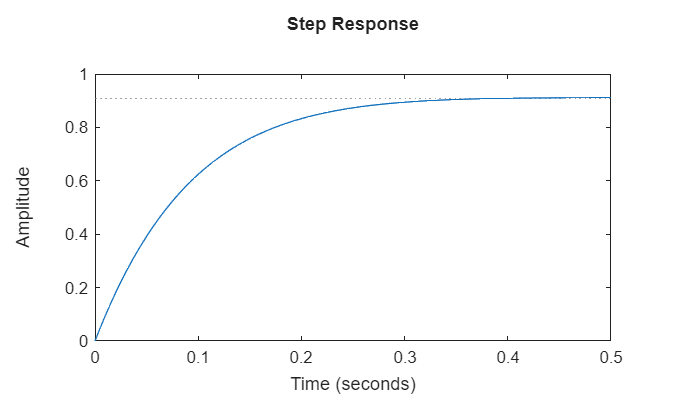

step(Gp)

%IMC
s=tf('s');
la = 0.1;
n = 3; %minimo de orden 2
F = 1/((la*s + 1)^n);
Q = F/Gp


Q =
 
             s^2 + 20 s + 110
  ---------------------------------------
  0.01 s^4 + 0.4 s^3 + 6 s^2 + 40 s + 100
 
Continuous-time transfer function.


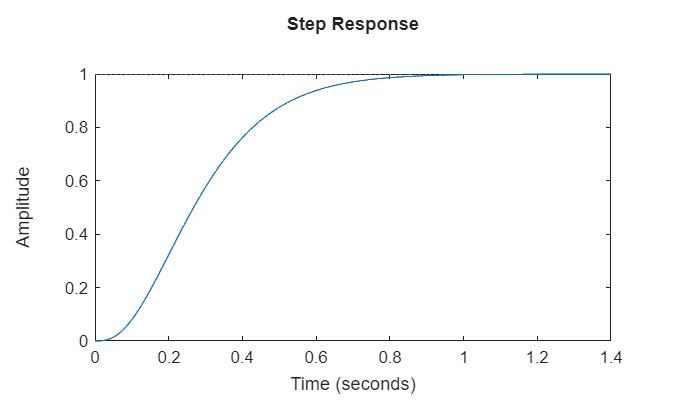

Gc=minreal(Q/(1-Gp*Q));
Gt = feedback(Gp*Gc, 1); %Gp*Gc/(1 + Gp*Gc); %
step(Gt);

stepinfo(Gt)

ans = struct with fields:
         RiseTime: 0.4221
    TransientTime: 0.7517
     SettlingTime: 0.7517
      SettlingMin: 0.9005
      SettlingMax: 0.9999
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9999
         PeakTime: 1.4487


%%Controlador predictivo

%% Discretizar el modelo
Ts = 0.2;
Spd = c2d(Sp, Ts, 'zoh');
Gpd = tf(Spd)


Gpd =
 
     0.8329 z - 0.1056
  ------------------------
  z^2 - 0.2183 z + 0.01832
 
Sample time: 0.2 seconds
Discrete-time transfer function.


b1 = Gpd.num{1,1}(2);
b2 = Gpd.num{1,1}(3);
a1 = Gpd.den{1,1}(2);
a2 = Gpd.den{1,1}(3);
%% Condiciones iniciales
yf = zeros(1, 2);
y = zeros(1, 2);
r = zeros(1, 2);
u = zeros(1, 2);

%% Definir horizontes
N1 = 1;
N2 = 10;
Nu = 1;
%% Respuesta al escalón
t = 0:Ts:(N2-1)*Ts;
g = step(Gpd, t) 

g =          0
    0.8329
    0.9091
    0.9105
    0.9094
    0.9091
    0.9091
    0.9091
    0.9091
    0.9091


% g(1) = b1;
% g(2) = -a1*b1 + b1 + b2;
% g(3) = -a1*g(2) - a2*g(1) + b1 + b2 + b3;
% for k = 4:1:N2
% g(k) = -a1*g(k-1) - a2*g(k-2) - a3*g(k-3) + b1 + b2 + b3;
% end

%% Parámetros MPC
du(1) = 0; %Cuanto cambia la ley de control
alfa = 0.8; %Para filtro
lambda = 0.01; %Peso del esfuerzo de control
%Modelo de tercer orden
T(1) = 0;
T(2) = Ts;
T(3) = 2*Ts;
MM = 1000;

%% Lazo de control
for t = 2:1:MM
    for k = 1:1:N2
    w(t+k)= 1; %Trayectoria deseada
    r(t+k) = alfa*r(t+k-1) + (1-alfa)*w(t+k); %Trayectoria de referencia
    yf(t+k) = -a1*yf(t+k-1)-a2*yf(t+k-2)+(b1+b2)*u(t-1); %Respuesta libre
    end
du(t) = (...
g(1)*(r(t+1)-yf(t+1))+g(2)*(r(t+2)-yf(t+2))+g(3)*(r(t+3)-yf(t+3))+ ...
g(4)*(r(t+4)-yf(t+4))+g(5)*(r(t+5)-yf(t+5))+g(6)*(r(t+6)-yf(t+6))+ ...
g(7)*(r(t+7)-yf(t+7))+g(8)*(r(t+8)-yf(t+8))+g(9)*(r(t+9)-yf(t+9))+ ...
g(10)*(r(t+10)-yf(t+10)))/(g(1)^2+g(2)^2+g(3)^2+g(4)^2+g(5)^2+ ...
g(6)^2+g(7)^2+g(8)^2+g(9)^2+g(10)^2+lambda);
u(t) = u(t-1) + du(t);
y(t+1)=-a1*y(t)-a2*y(t-1)+b1*u(t)+b2*u(t-1);
T(t+1) = T(t) + Ts;
end

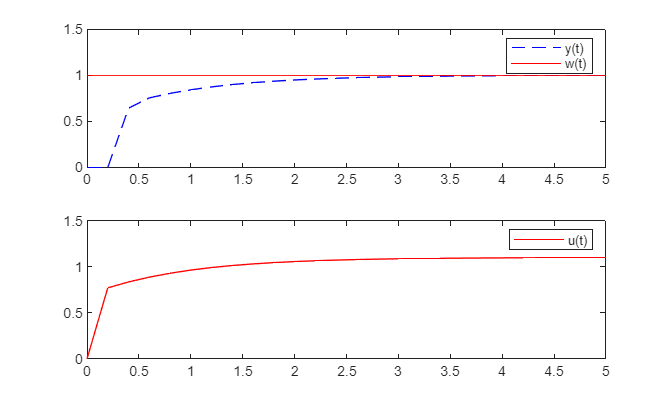


figure, subplot(2,1,1), plot(T,y,'b--',T,w(4:1004),'r');
legend('y(t)', 'w(t)');
ylim([0 1.5])
xlim([0 5])
subplot(2,1,2),plot(T(1,1:end-1),u,'r');
legend('u(t)');

ylim([0 1.5])
xlim([0 5])